# 流動様式判別（マルチモーダル学習）

最初にこれを実行してください. 見やすくなるおまじないです. 

s = settings;
s.matlab.fonts.editor.title.Style.PersonalValue = {'bold'};
s.matlab.fonts.editor.title.Color.PersonalValue = [0 0 255 1];

# 0. ワークスペースの掃除・開いている図の削除

matlabでは

clcでコマンドラインの履歴の削除

clearでワークスペースの変数の削除. 

close all hiddenで最小化されているグラフも含めて全て削除

することが出来ます. 

 
clc;
clear;
close all hidden;

# 1. Excelデータの取り込み

RawDataTwoクラスによってExcelデータを取り込みます. 

% 1. RawDataの作成
dataCreator = RawDataCreatorTwo();
trainRawDataArray = dataCreator.create("20251114", 100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);
testRawDataArray  = dataCreator.create("20251117", 100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);
% trainData, testDataをRawDataTwo配列として保持しました。

% 2. rawAllData のインスタンス作成
% RawDataTwo 配列の結合
rawAllData = RawAllDataBeforeFormatTwo([trainRawDataArray, testRawDataArray]); 

% 3. 前処理の実行と ModifiedDataBeforeFormatTwo の取得
preProcessor = PreProcessorBeforeFormatTwo({@intervalUniformerTwo, @correctWithCapacitanceBaseTwo});

% 訓練データとテストデータの配列を取得
modifiedTrainDataArray = preProcessor.process(trainRawDataArray, rawAllData);

modifiedTestDataArray  = preProcessor.process(testRawDataArray, rawAllData);

% trainData, testDataという変数名は、ModifiedDataBeforeFormatTwo配列を指すことになります。
% trainData = modifiedTrainDataArray;
% testData = modifiedTestDataArray;

# 2. データ拡張(スライディングウィンドウ法)

一個ずらしのx点で切り取ってデータを増やします. 

 
stride = 1; %各データごとに何計測点飛ばすか. ふつうは1
dataWidth = 400; % データ幅. ここは調整して良い. いつもは300で統一
interval = 0; %データをいくつ飛ばしでdataWIdth点だけ取るか. ふつうは0

% 1. DataFormatterOption クラスのインスタンスを作成し、すべてのオプションを指定
%    これにより、オプションが DataFormatterOption オブジェクト内にカプセル化されます。
optionObject = DataFormatterOption(...
    stride, ...
    dataWidth, ...
    interval, ...
    'lengthLimitInEachCondition', intmax("int16"), ...
    'channels', 400, ... 
    'featureChannels', 4, ... 
    'useWaveform', true, ...  % <-- 入力構成を選択 true：波形入力オン、false：波形入力オフ
    'useFeature', true ...    % <-- 入力構成を選択 true：特徴量入力オン、false：特徴量入力オフ
);

% --- データ整形と特徴量統合 (DataFormatterTwo の実行) ---
dataFormatterCreator = DataFormatterCreatorTwo(optionObject); 
dataFormatter = dataFormatterCreator.create();

% DataFormatterTwoを実行し、FormattedDataTwo配列を取得
% 訓練データ
trainFormattedDataArray = dataFormatter.Format(modifiedTrainDataArray);

--- 🔍 DataFormatterTwo.Format: obj.useWaveform の値: 1 ---
'Processes' プロファイルを使用して並列プール (parpool) を起動中...
6 個のワーカーをもつ並列プールに接続されています。



% テストデータ
testFormattedDataArray  = dataFormatter.Format(modifiedTestDataArray);

# 3. 訓練及びテストデータ作成(分類)

trainTestDataCreator = TrainTestDataCreatorTwo();
dummyFunc = @(x) x;

[trainCapWave, trainDiffWave, trainFeature, trainLabel, ...
 testCapWave, testDiffWave, testFeature, testLabel] = ...
 trainTestDataCreator.createMultimodalInputs(...
     trainFormattedDataArray, ...
     testFormattedDataArray, ...
     dummyFunc);

% 必要なメタデータ（ワークスペースの既存変数から取得を推奨）
minLen = size(trainCapWave{1}, 1); % 2553
condStr = trainFormattedDataArray(1).condition; % 1x12 string
labelStr = unique(trainLabel); % categoricalから取得

% TrainTestDataTwo の新しいコンストラクタに合わせてデータを渡す
trainDataInstance = TrainTestDataTwo(...
    trainCapWave, ...
    trainDiffWave, ...
    trainFeature, ...%生データ
    trainLabel, ...
    minLen, ...
    condStr, ...
    labelStr ...
);

testDataInstance = TrainTestDataTwo(...
    testCapWave, ...
    testDiffWave, ...
    testFeature, ...%生データ
    testLabel, ...
    minLen, ...
    condStr, ...
    labelStr ...
);

Z-score 標準化コードの挿入 (FeatureData を更新)

% 1. 訓練データに基づいて平均 (mu) と標準偏差 (sigma) を計算
trainFeatureData = trainDataInstance.FeatureData;
mu_feature = mean(trainFeatureData, 1);
sigma_feature = std(trainFeatureData, 0, 1);

% 2. 標準偏差がゼロ (定数) の特徴量に対する安全策
sigma_feature(sigma_feature == 0) = 1;

% 3. 標準化を訓練データとテストデータに適用
normalized_trainFeature = (trainFeatureData - mu_feature) ./ sigma_feature;
testFeatureData = testDataInstance.FeatureData;
normalized_testFeature = (testFeatureData - mu_feature) ./ sigma_feature;

% 4. TrainTestDataTwo インスタンスの再作成と更新 (FeatureData を標準化済みデータで置き換え)
trainDataInstance = TrainTestDataTwo(...
    trainDataInstance.CapWaveData, ...
    trainDataInstance.DiffWaveData, ...
    normalized_trainFeature, ... % ★ 標準化済み FeatureData で更新 ★
    trainDataInstance.label, ...
    trainDataInstance.minimumLength, ...
    trainDataInstance.conditionStrings, ...
    trainDataInstance.labelStrings ...
);

testDataInstance = TrainTestDataTwo(...
    testDataInstance.CapWaveData, ...
    testDataInstance.DiffWaveData, ...
    normalized_testFeature, ... % ★ 標準化済み FeatureData で更新 ★
    testDataInstance.label, ...
    testDataInstance.minimumLength, ...
    testDataInstance.conditionStrings, ...
    testDataInstance.labelStrings ...
);

disp('FeatureData の Z-score 標準化が完了しました。trainDataInstance および testDataInstance が更新されました。');

FeatureData の Z-score 標準化が完了しました。trainDataInstance および testDataInstance が更新されました。


データの保存

% 2つのインスタンスを直接保存
save('trainDataInstance.mat', 'trainDataInstance');
save('testDataInstance.mat', 'testDataInstance');

# 4. 訓練設定(分類)

訓練を始める前に

- どんな方法で訓練を行うのか, 

- そもそも深層学習の層をどのように組むのか

を決定します. 

% --- 訓練オプションとレイヤー設定インスタンスの作成 ---
classificationTrainOptionCreator = TrainOptionCreatorTwo(trainDataInstance, testDataInstance);
layerSettingCreator = LayerSettingCreatorTwo(trainDataInstance, testDataInstance);

 
initialLearnRate = 0.0025552;
maxEpoch = 80; % データ全てを何周したら訓練を終わらせるか. 1周は全データが深層学習に一回は入力されたことを意味する(厳密には異なるが)
miniBatchSize = 32;% 一回で深層学習にどれだけのデータを食わせるか. 確率勾配法の肝. まぁとりあえず64でいいかという感じ. 
frequency = 150; % 訓練何回ごとに検証データを入力して上手く学習が進んでいるのかどうかを判断する. 
trainRepeatAmount = 1;% 何回訓練と精度確認を行うか. 精度上昇の効果が見られたとしてもそれがちゃんと再現性のある結果なのかどうかを判断するときに使う.
                                            %x回まわして殆ど全ての場合で精度向上が見られたらokみたいな. 
toleranceTimesForNotImproving = 20; % 訓練中に検証データを入れて, この回数だけ精度の向上が無かった場合には訓練を修了する.

% --- ネットワークパラメーターの設定 ---
% ワークスペースの trainDataInstance から取得
capInputSize = trainDataInstance.minimumLength; 
diffInputSize = trainDataInstance.minimumLength;
featureInputSize = size(trainDataInstance.FeatureData, 2); % 3

% --- 調整可能なハイパーパラメーター（初期設定） ---
hiddenUnitAmount = 100; 
denseUnitAmount = 50;

% オプションと LayerGraph の構築
option = classificationTrainOptionCreator.createNormalTrainOption(initialLearnRate, maxEpoch, miniBatchSize, frequency, trainRepeatAmount, toleranceTimesForNotImproving);
layer = layerSettingCreator.createMultimodalLayerGraph(capInputSize, diffInputSize, featureInputSize, hiddenUnitAmount, denseUnitAmount);

# 5. 訓練開始(分類)

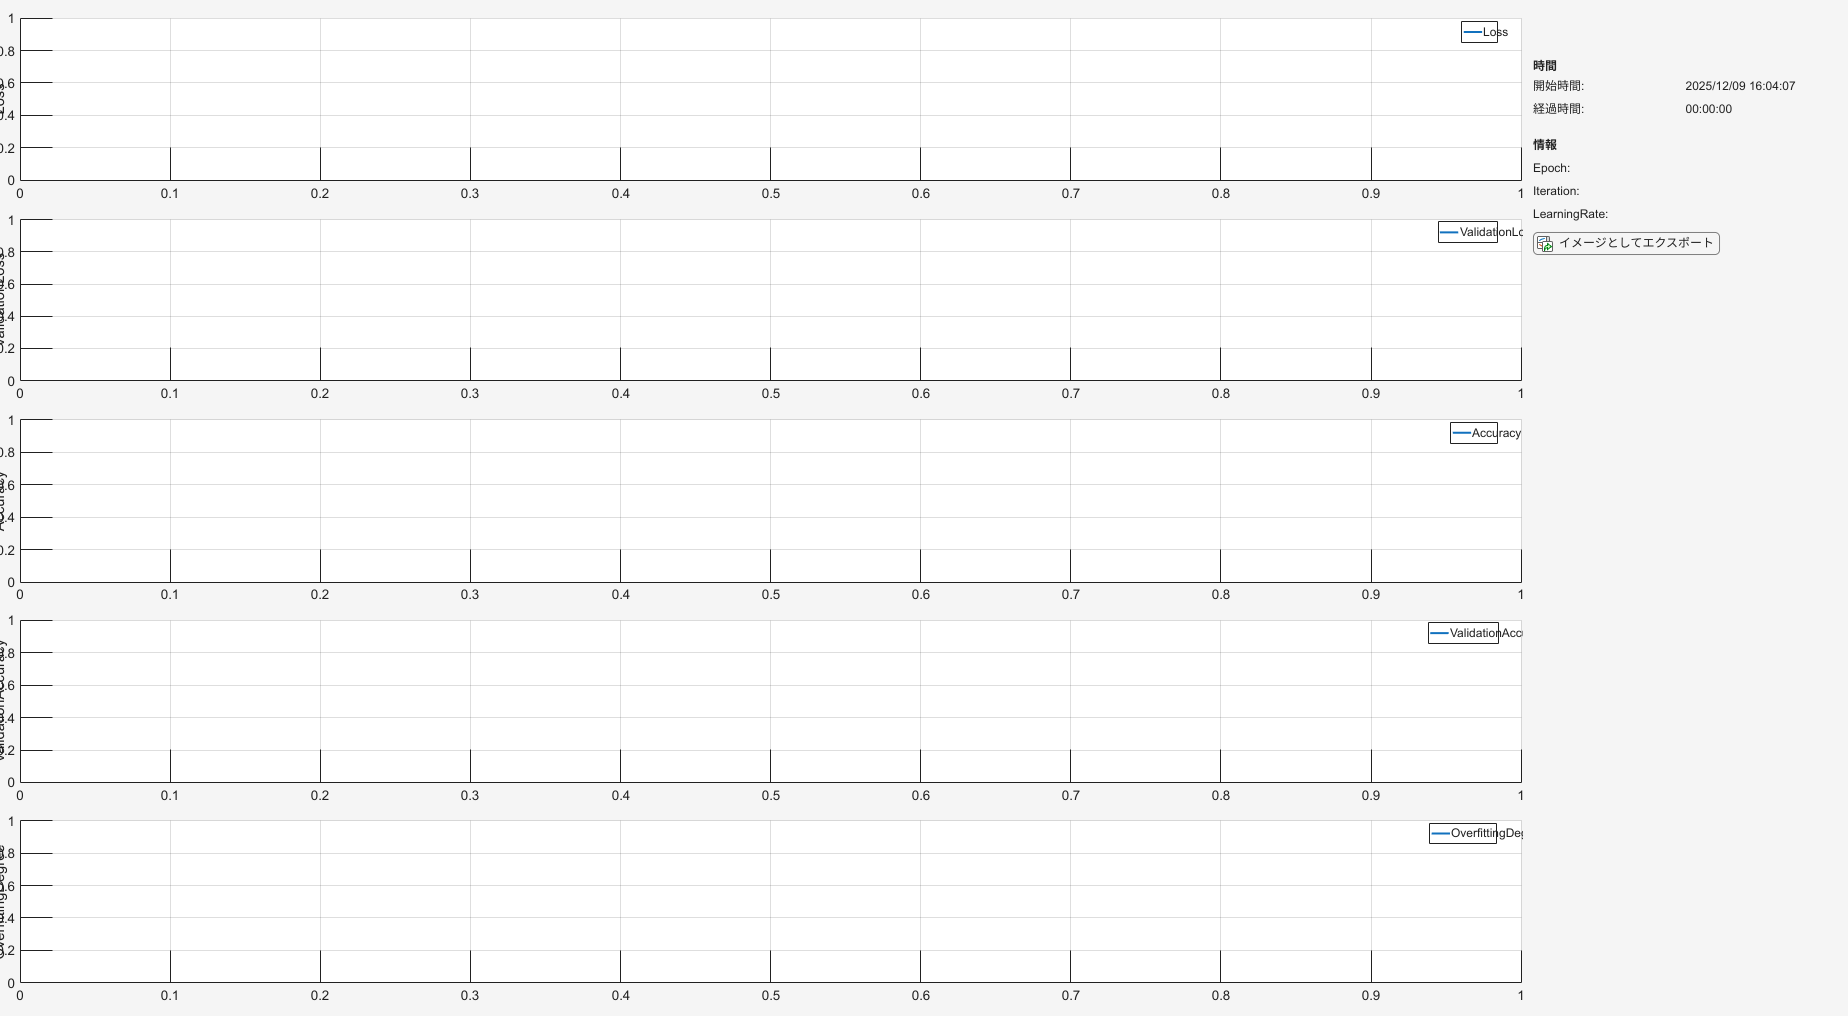

次を使用中のエラー: matlab.io.datastore/CombinedDatastore/read
入力引数が多すぎます。

エラー: TrainActivatorTwo/customActivateMultimodal (行 318)
                    [capCell, diffCell, featCell, Tcat] = read(dsTrain, 'BatchSize', miniBatchSize); 
                    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

% === 1. 保存設定の動的生成 (修正箇所) ===
% 訓練結果を保存するユニークなディレクトリ名を作成
netSaveDirectory = fullfile("results", datestr(now, "yyyymmdd_HHMMSS")); 
netSaveName = "multimodal_net_01.mat"; 

% TrainActivatorTwo インスタンスの作成
trainActivator = TrainActivatorTwo(...
    trainDataInstance, ...
    testDataInstance, ...
    option, ...
    layer, ...
    'netSaveName', netSaveName, ...
    'netSaveDirectory', netSaveDirectory ...
);

% === 2. 訓練の実行（必須修正箇所）===
% 正しいカスタム学習関数を引数なしで呼び出す
[trainedNet, trainInfo] = trainActivator.customActivateMultimodal();


fprintf('訓練が完了しました。結果は %s に保存されています。\n', netSaveDirectory);

# 6. 結果の表示(分類)

 

resultDisplyer = ResultDisplayerTwo(result,option);
resultDisplyer.displayResult(folderName);

# 7. それでは損失関数を変えてみましょう. 

ここまでは損失関数はcrossrntropyの通り, シンプルなクロスエントロピー誤差でやっていました. ところで, 深層学習にはoverConfidenceという現象があります. モデルが自信過剰になるものですね. あいまいなところはあいまいで良いのに... 

こういうのに対して損失関数から攻める方法があります. (cf. [https://zenn.dev/bilzard/scraps/d3875d0c5c5e92)](https://zenn.dev/bilzard/scraps/d3875d0c5c5e92))

というわけで, Label Smoothingを使ってみましょう.

なお, 他のloss func: https://knto-h.hatenablog.com/entry/2018/10/09/170000

まずは損失関数の定義からです. 

※定義自体はここではなく, Class->DeepLearning->TrainNet->classification->lossFunc->singleClasssificationに書いてください. (書いた)

次のように損失関数は定義します. 

%{
function func = labelSmoothing(outputLayerName)
arguments
    outputLayerName string
end
%LABELSMOOTHING 正解ラベルの値を1でなく1よりも少しだけ小さな値にすることで、logitが発散するのを抑制する手法。
% cf. https://zenn.dev/bilzard/scraps/d3875d0c5c5e92
% 学習率と連動させてオンライン化するのも面白いかもね. https://qiita.com/T-STAR/items/a3bdcd1ae00150fe1402
function [loss,gradients,state] = labelSmoothingCore(net,trainData,label)
        [predictedLiquid, state] = forward(net,trainData,Outputs=[outputLayerName]);
        %Loss Functionを改造したい時はこの一行を変えてください. ================================
        %predictedLiquid は条件数(12条件とか)*MiniBatchSize(64とか)のdlArrayです. 
        %labelも同じです. どちらもone-hot-表現で出てきます. 
        noise = 0.3; % これ, 色々変えてみてください.  正解クラス以外にどれだけノイズを分配するかです. 
        modifiedTarget = label*(1-noise)+noise/size(label,1);
        lossBeforeMean = -sum((modifiedTarget).*log(predictedLiquid));
        loss = mean(lossBeforeMean); % ミニバッチのため,平均化
        %======================================================================================
        gradients = dlgradient(loss,net.Learnables);
    end
func = @labelSmoothingCore;
end


それではこの損失関数を使った場合の結果を見てみましょう. 

 
% 訓練を担当するクラス 
trainActivator = TrainActivator(train,test,option,layer);
prefix = "helloWorld/";
folderName = append(prefix,"test-3-labelSmoothing/");
% 結果が格納されたクラス (カスタム損失関数の時は関数変わります)
result = trainActivator.customLossFuncActivate("softmax",@labelSmoothing,folderName);

# ８．結果の表示

損失関数を変化させた場合の結果の表示をしましょう. 

 
resultDisplyer = ResultDisplayer(result,option);
resultDisplyer.displayResult(folderName);
%}

どうでしょうか, 何か変わりましたかね? 私は確認していないのでここからはあなたが責任を持って結果を解析してみてください. 

# ９．ベイズ最適化

ハイパーパラメータの最適化を行うためのコードです。（2025〜）

% 最適化パラメータの定義
% 過学習を表す指標を追加したい
vars = [
    optimizableVariable('InitialLearnRate', [1e-4, 1e-2], 'Transform', 'log')
    optimizableVariable('MaxEpoch', [10, 100], 'Type', 'integer')
    optimizableVariable('MiniBatchSize', [32,128], 'Type', 'integer')
    optimizableVariable('HiddenUnitSize', [128, 512], 'Type', 'integer')
];


% 最適化実行’
results = bayesopt(@optimizeModelTwo, vars, ...
    'MaxObjectiveEvaluations', 20, ... % 試行回数
    'AcquisitionFunctionName', 'expected-improvement-plus', ...
    'Verbose', 1, ...
    'PlotFcn', {@plotMinObjective,@plotElapsedTime});
   % 'UseParallel',true %配列化


bestParams = bestPoint(results);
disp(bestParams);

# 10. 最適なパラメータでの混同行列の表示

2025~

1. 最適なハイパーパラメータの抽出 


% bestParamsから最適値を抽出
initialLearnRate = bestParams.InitialLearnRate;
maxEpoch = bestParams.MaxEpoch;
miniBatchSize = bestParams.MiniBatchSize;
hiddenUnitSize = bestParams.HiddenUnitSize;

% NOTE: 'train.mat' と 'test.mat' がワークスペースに残っていることを前提

 2. optimizeModelTwoのロジックを再現 


% 2-1. 学習オプション作成 (optimizeModelTwo内の設定を再現)
classificationTrainOptionCreator = TrainOptionCreatorTwo(train, test);
trainOptionObj = classificationTrainOptionCreator.createNormalTrainOption(...
    initialLearnRate, maxEpoch, miniBatchSize, ...
    150, 1, 20); % frequency=150, repeat=1, tolerance=20
option_best = trainOptionObj.option;

% 2-2. レイヤー構築 (optimizeModelTwo内の設定を再現)
layerSettingCreator = LayerSettingCreatorTwo(train, test);
inputsize = 2; % 圧力 + 静電容量の2系列
layers_best = layerSettingCreator.createSingleLSTMLayer(inputsize, hiddenUnitSize);

 3. ベストモデルの訓練を再実行

net_best = trainNetwork(train.data, train.label, layers_best, option_best);

4. 混同行列の表示と指定フォルダへの保存 

% 4-1. 日付情報の取得とファイル名・タイトルの準備
timestamp = string(datetime('now','Format','yyyyMMdd_HHmmss'));
titleTimestamp = string(datetime('now','Format','yyyy-MM-dd HH:mm:ss'));

baseSaveDir = '/home/twophaseflow/deepLearningForMultiMeter/deepLearningForMultiMeter/File_MURATA_Flow_Regime/ConfusionMatrix_PNG';
% 実行日時を名前にした新しいサブフォルダを作成 (例: .../ConfusionMatrix_PNG/20251112_133013)
saveDir = fullfile(baseSaveDir, timestamp);

if ~exist(saveDir, 'dir')
    mkdir(saveDir);
end

fileName = fullfile(saveDir, ['confusion_matrix_' timestamp '.png']);

% 4-2. 評価
YPred_best_test = classify(net_best, test.data);
YTrue_test = test.label;

% 4-3. 混同行列の表示
figure('Visible', 'on'); % 図を表示
h = confusionchart(YTrue_test, YPred_best_test); 
title(['Best Model Confusion Matrix - ', titleTimestamp]); % 日付をタイトルに追加

% 4-4. 画像ファイルとして保存
saveas(gcf, fileName);